# Disease Modeling Programming in MATLAB

## Introduction

This MATLAB program is an example of a "Kermack-McKendrick Model" in epidemic modeling.

This is also a good example of 

- Programming in MATLAB

- Creating a Policy-Relevant Model

- Illustrating  how to code coupled systems of equations.

- Why you should be getting your flu shot.

The basics of a Kermack-McKendrick Model is that you have [typically] three sub-populations in a community where something icky is going around.  This is normally called an "SIR" Model:

- Susceptibles  : people who in principle can get sick (in this case we will bundle a block of people who are immunized into this block)

- Infected : people who have the disease and can spread it into the Susceptable population

- Recovered: people who have had the disease and are now immune.

To this category we're adding a "Fatal" category because we *are* monsters.  

Other versions of this system can distribute the Infected category into subgroups that symptomatic (changing their behavior in contrast to the other classes [not including the dead], contagious [at different levels of symptomatic or asymptomatic]).  

You can break the "Susceptible" group into those with temporary immunity from their mothers, permanent immunity by random chance, and immunity from immunization.  

You can have recovered people who have been infected lose their immunity.  

In short, you can let your Pestilence Horseman run wild because “it’s only a model.”

## Sketching the Model Environment and the Kermack-McKendrick Equations

It's always nice to sketch and doodle our models. The black letters will be our variables.  (We're not doing the "cordon sanitaire" option (where healthy people wall themselves off from the sick people) in this example.

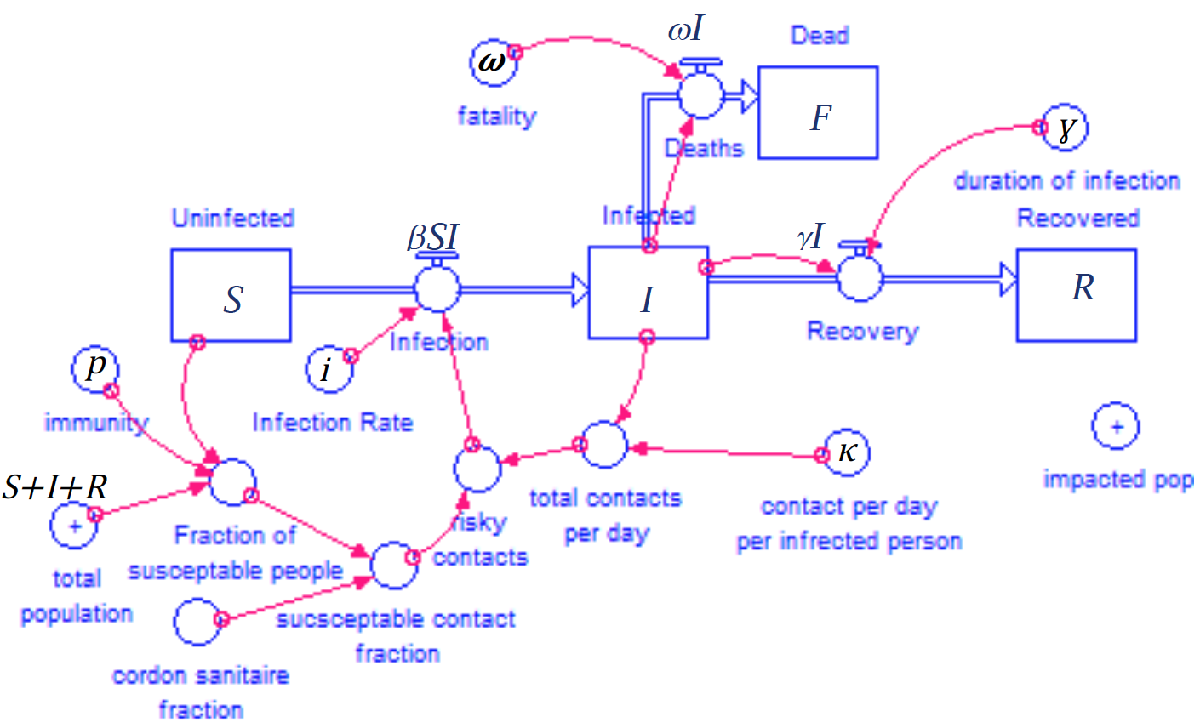

The boxes are our main players from above.  The circles are the factors that influence the epidemic.  (These become the Left-Hand-Side of our equations.)  The red arrows are what connect the factors to what eventually will be what's on the Right-Hand-Side of the equations).  Sources and Sinks from our main factors are collected in the blue arrows.

## 
$$\begin{array}{l}
\frac{\partial }{\partial t}S=-\beta \mathit{SI}\\
\frac{\partial }{\partial t}I=+\beta \mathit{SI}-\gamma I-\omega I\\
\frac{\partial }{\partial t}R=+\gamma I\\
\frac{\partial }{\partial t}F=+\omega I
\end{array}$$


The greek letters above will be explained as we go.

## Setting up the Code

To do this we will break this process down into several sub-sections

- We will do time control (set up the period of our simulation) 

- We will create the variables for which we will preduct (our Sick, Healthy, Recovered and Dead people)

- We then will set up the parameters that describe how our disease will behave

- We will integrate forward in time with a basic Euler’s “solver” for our system of equations.

- Then plot our output

First let’s set up the time control of our simulation.

## Time Control

This part is easy.  We just put together our time steps and the duration of the scenario.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%
% Time Control 
%

delta_t =   0.01;    % delta_t in days
time_0 =    0.00;    % time_0 and time_f are start and end days
time_f =   90.00;    %   for this case we are playing the "short game"

% Calculating Basic Time Variables

nt     = (time_f - time_0) / delta_t  + 1; % number of time steps
time   = time_0:delta_t:time_f;            % time in days array created

%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


## Population Demographics

With our time set up we can now create a set of “players” in this game

- Susceptables (people who have not acquired the illness)

- Infected (people who have acquired the illness and in this scenario are showing symptions AND are contagious)

- Recovered (people who have recovered from the illness and are no longer infectious)

- Fatalities (people who had the illness but are no longer breathing or doing much of anything else)

And we'll start with 5000 players with one of them returning from Spring Break with... ok that's for later.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%
% Population Initializations
%

S0  = 4999;    % initial susceptible (healthy) cases
I0  =    1;    % initial infected cases
R0  =    0;    % initial recovered (immune) cases
F0  =    0;    % inital fatal cases

%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


## #We'reDoingShots!

In this case we can play with a fraction of the population that enter the game with either natural immunity or have been immunized.

You acutally can calculate the threshold immunity (heard immunity) of where a disease will not spread through the community.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%
% Immunization Program 
%

initial_fraction_of_population_immunized = 0.00; % fraction of population immunized (0-1)

%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


## Disease Traits

Now onto the disease:  We will need to have the

- the likely number of people who an infected person comes into contact per unit time (i)

- the probability of infection when a truly vulerable person is exposed per unit time (kappa)

- the probability of recovery per unit time for a given infected person (gamma)

- the probability per unit time of an infected person dying from the disesase (omega)

Beta from the above equation system is a little more complex than the original case and is a combination of several of these terms.

If we want to include factors like artificial or natural immunity (p) we can include that, too.  You can get this through some unit analysis.


$$\begin{array}{l}
\beta =\frac{i\;k\;\left(1-p\right)}{S+I+R}\\
\beta \left\lbrack \frac{\;\;\mathrm{new}\;\mathrm{infection}\;}{\mathrm{contact}\;\mathrm{of}\;\mathrm{the}\;\mathrm{sick}\;\mathrm{with}\;\mathrm{susceptables}*\mathrm{day}}\right\rbrack =\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(1-p\right)\left\lbrace \left\lbrack \mathrm{unvaccinated}\;\mathrm{fractioni}\right\rbrack \right\rbrace \left\lbrace i\left\lbrack \frac{\;\mathrm{chance}\;\mathrm{of}\;\mathrm{new}\;\mathrm{infection}\;}{\mathrm{contact}\;}\right\rbrack \right\rbrace \;\left\lbrace k\left\lbrack \frac{\;\mathrm{contacts}}{\mathrm{day}}\right\rbrack \right\rbrace \left\lbrace \frac{\left\lbrack \mathrm{chance}\;\mathrm{of}\;\mathrm{encontering}\;\mathrm{any}\;\mathrm{specific}\;\mathrm{person}\right\rbrack }{\left(S+I+R\right)}\right\rbrace 
\end{array}$$


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%
% Disease Characteristics
%

contact_rate   = 6.00; % typical number of contacts (exposure) per case per day
infection_rate = 0.25; % probabilty of infection on exposure per case per day
fatality_rate  = 0.00; % mean chance of fatality per case per day
recovery_rate  = 0.50; % mean chance of recovery per day per case per day

%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Value-added Parameters

If you ever saw the medical thriller "Contagion" the [CDC Epidemiologist played by Kate Winslet gives a description of something called the "R-nought" (or Ro) factor while plague-splaining public health metrics to city planners](https://www.youtube.com/watch?v=VrATMF_FB9M) (see the link).

The $R_0$ describes how many people one infected person wil infect.

$R_0$'s greater than 1 indicate a disease that will spread through the population.  The higher the $R_0$, the faster the spread.  $R_0$'s below 1 will likely self-contain due to low probability if infection (not every case will result in a new case but an influx of sick people may create a critical mass of "players" for some "Susceptables" to loose to the odds). 

Using our parameters we can define $R_0$


$$R_0 =\frac{i\;k}{\left(\gamma +\omega \right)}$$


You can get this by borrowing from the various disease traits and doing some unit analysis.


$$R_0 \left\lbrack \frac{\mathrm{typical}\;#\;\mathrm{of}\;\mathrm{new}\;\mathrm{infections}\;}{\mathrm{case}}\right\rbrack =\left\lbrace i\left\lbrack \frac{\mathrm{typical}\;\mathrm{chance}\;\mathrm{of}\;\mathrm{new}\;\mathrm{infection}\;}{\mathrm{contact}}\right\rbrack \right\rbrace \;\left\lbrace k\left\lbrack \frac{\mathrm{typical}\;\mathrm{contacts}}{\mathrm{day}}\right\rbrack \right\rbrace \;\;\;\left\lbrace \frac{1}{\left(\gamma +\omega \right)}\left\lbrack \frac{\mathrm{typical}\;\mathrm{days}}{\mathrm{case}}\;\right\rbrack \right\rbrace$$


Measles for example has an $R_0$ of 12-18; the Spanish Flu pandemic after WW1 was 2-3.  Polio is 5-7, each depending on its method of contact.  AIDS while not airborne has a 2-5 $R_0$ through blood contacts.  Same with the limited conduits by which one can contract Ebola (from bodily fluids) with its $R_0$ of 1.5-2.5.  That child with Pertussis (Whooping Cough) a Ph.D. student once brought into my office one day had an $R_0$ between 5 & 6 (so get your [TDAP booster](https://www.cdc.gov/vaccines/schedules/hcp/imz/adult.html)!).

With the $R_0$ we can also play with the numbers with some Algebra-Fu so that we can solve for *p* where $\frac{\partial }{\partial t}I=0$ and assume that $S>>\left(I+R\right)$.  We can then use that to determine the critical herd immunity (*p*) by which we can stop the spread of the disease.


$$\begin{array}{l}
\frac{\partial }{\partial t}I=\frac{i\;k\;\left(1-p\right)}{S+I+R}S\;I-\left(\gamma +\omega \right)I\\
0=\frac{i\;k\;\left(1-p\right)}{S+I+R}S\;I-\left(\gamma +\omega \right)I\\
0=\frac{i\;k\;\left(1-p\right)}{S}S\;I-\left(\gamma +\omega \right)I\\
0=I\left\lbrack \frac{i\;k\;\left(1-p\right)}{S}S-\left(\gamma +\omega \right)\right\rbrack \\
0=I\left\lbrack i\;k\;\left(1-p\right)-\left(\gamma +\omega \right)\right\rbrack \\
0=i\;k\;\left(1-p\right)-\left(\gamma +\omega \right)\\
i\;k\;\left(1-p\right)=\gamma +\omega \\
1-p=\frac{\;\gamma +\omega }{i\;k}\\
1-p=\frac{1}{R_o }\\
p=1-\frac{1}{R_o }
\end{array}$$


For the parameters we established above (unless you messed with them), the default traits of the disease creates an $R_0$ of 3 which requires a herd immunity of 2/3's (2/3's of the population needs immunity for the disease to die out).

(For measles the $R_0$, herd immunity is in the high 90% range which is why the anti-vaccination movement is well....  You do the math.)

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%
% Basic Repoduction Rate (Ro), the one they talk about in movies
%    number of people infected from a single case
%    Ro < 1 the disease will quickly die out and be localized
%    Ro = 1 the disease will hover in a population but should not grow
%    Ro > 1 the disease will spread through the population

Ro = infection_rate * contact_rate / (recovery_rate+fatality_rate);  

%
% Critical Herd Immunity, Po, the fraction of the population that must
%   be naturally or artifically immune so that Ro drops below 1 and the 
%   disease dies out.  With this closed population case this can happen
%   before the disease reaches everyone in the population.  

Po = max(0, 1-1/Ro);     % critical herd immunity (fraction, 0-1)

%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


## Starting the Actual Code... 

This first section is just doing basic diagnostic print-outs.   Like I said most "notebook" type formats such as MATLAB's live scripts could use some improvement.  My approach is now to string a very long string of a block of text output and use the *newline* function in MATLAB to break the lines up.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%
% Print Initial State
%
%   I am not fond of doing print output in MATLAB but this works for me.
%     You "bracket" what you want to say in little strings.  When you need
%     to print a number, wrap it up in a num2str() function.
%

disp(['          Contact Rate : ',num2str(contact_rate),' contacts per infected people per day ',     newline ...
      '         Infecton Rate : ',num2str(infection_rate),' new cases per exposure per day',          newline ...
      '         Fatality Rate : ',num2str(fatality_rate),' mean chance of fatality per case per day', newline ...
      '         Recovery Rate : ',num2str(recovery_rate),' mean chance of recovery per case per day', newline ...
      newline, ...                                                                                            
      'Basic Reproduction Rate (Ro) : ',num2str(Ro),' new infections per infected case',              newline ...
      '     Actual Percent Immunity : ',num2str((initial_fraction_of_population_immunized*100.)),'%', newline ...
      '      Critical Herd Immunity : ',num2str(Po*100.),'%',                                         newline ...
      ' ']);

          Contact Rate : 6 contacts per infected people per day 
         Infecton Rate : 0.25 new cases per exposure per day
         Fatality Rate : 0 mean chance of fatality per case per day
         Recovery Rate : 0.5 mean chance of recovery per case per day

Basic Reproduction Rate (Ro) : 3 new infections per infected case
     Actual Percent Immunity : 0%
      Critical Herd Immunity : 66.6667%
 


%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


Now let's make the population.  Here we "borrow" the time variable from above (because I'm fine with maximum satisfaction with minimal effort) and create a set of "zero" arrays by multiplying time by zero.

Then I am just setting the first index (and MATLAB starts indexing at "1") to our initial number of players on each team from above.


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%
% Create Demographic State Variables (i.e., the people)
%
% I'm using a lazy trick here by basically using the time variable
%   we made above to serve as the backbone by which we can make the
%   other variables (we're just multiplying them by zero).
%

S = time * 0; % susceptible cases array created ("cloned" from time)
I = time * 0; % infected cases array created
R = time * 0; % recovered cases array created
F = time * 0; % fatal cases array created

%
% Initiaize Demographic State Variables (i.e., the people)
%

S(1) = S0; % susceptible cases initialized
I(1) = I0; % infected cases initialized
R(1) = R0; % recovered cases initialized
F(1) = F0; % fatal cases initialized

%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


## And Away We Go! (Marching through Time)

Now it's time to march forward in time.

We are coding with Euler's Method (a cheap way to march forward in time from Differential Equations but requires tiny time steps).

Euler's Method works thusly.

Let's take just one of our equations, the S, equation.


$$\frac{\partial }{\partial t}S=-\beta \textrm{SI}$$


If we use a Taylor Series and chop off anything above our first-order terms we get a system that looks like this.


$$\begin{array}{l}
x\left(t+\Delta t\right)=x\left(t\right)+\left\lbrack \frac{\mathrm{d}}{\mathrm{d}t}x\left(t\right)\right\rbrack \Delta t+\frac{1}{2!}\left\lbrack \frac{{\textrm{d}}^2 }{\textrm{d}t^2 }x\left(t\right)\right\rbrack \Delta t+\frac{1}{3!}\left\lbrack \frac{{\textrm{d}}^3 }{\textrm{d}t^3 }x\left(t\right)\right\rbrack \Delta t\ldotp \ldotp \ldotp \\
x\left(t+\Delta t\right)=x\left(t\right)+\left\lbrack \frac{\mathrm{d}}{\mathrm{d}t}x\left(t\right)\right\rbrack \Delta t
\end{array}$$


thus...


$$\begin{array}{l}
S\left(t+\Delta t\right)=S\left(t\right)+\left\lbrack \frac{\mathrm{d}}{\mathrm{d}t}S\left(t\right)\right\rbrack \Delta t\\
S\left(t+\Delta t\right)=S\left(t\right)+\left\lbrack -\beta I\left(t\right)S\left(t\right)\right\rbrack \Delta t
\end{array}$$


We sometimes call this equation and the part of the modeling program that contains it "The Solver"

Applying this model to all five of our equations...


$$\begin{array}{l}
S\left(t+\Delta t\right)=S\left(t\right)+\left\lbrack -\beta I\left(t\right)S\left(t\right)\right\rbrack \Delta t\\
I\left(t+\Delta t\right)=I\left(t\right)+\left\lbrack \beta I\left(t\right)S\left(t\right)-\gamma I\left(t\right)-\omega I\left(t\right)\right\rbrack \Delta t\\
R\left(t+\Delta t\right)=R\left(t\right)+\left\lbrack \gamma I\left(t\right)\right\rbrack \Delta t\\
F\left(t+\Delta t\right)=F\left(t\right)+\left\lbrack \omega I\left(t\right)\right\rbrack \Delta t
\end{array}$$


The $X\left(t+\Delta t\right)$represents the previous time step.  $X\left(t\right)$is the timestep we're solving for.  And if we keep our $\Delta t$ small relative to our rate of change, (think of it as "not driving past your headlights" ), we can model our system of the quick and the dead (and the people who are stuck in bed).


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%
% Integrate using a simple Euler's Method approach like we did in class
%

for k = 2:nt  % we already have time step [#1]!

    % calculating critical fields for Kermack-McKendrick Theory
    
    % we could use these later but we're just collecting the dots here
    %   from the above cartoon that showed the entire system.
    
    total_people = S(k-1) + I(k-1) + R(k-1);  % calculated here in case
                                              % we expand to having
                                              % births and deaths
                                              % should we want to turn
                                              % our short game to a long
                                              % game

    fraciton_of_susceptable_healthy = S(k-1) / total_people;

    total_infected_contacts_per_day  = I(k-1) * contact_rate;

    exposures_per_day  = fraciton_of_susceptable_healthy * total_infected_contacts_per_day;

    % creating the simple Kermack-McKendrick Theory coefficients;

    % note: beta normally does not include immunity rates.  they go 
    %       into another population group but we are keeping it in the
    %       main equations
    
    P       = initial_fraction_of_population_immunized;
    
    beta    = infection_rate * contact_rate * (1-P);

    N       = total_people;

    gamma   = recovery_rate;

    omega   = fatality_rate;
    
    %  Solving the  K-McK equations in derivative form

    dSdt = -(beta/N) * S(k-1) * I(k-1);
    dIdt =  (beta/N) * S(k-1) * I(k-1) - (gamma + omega) * I(k-1);
    dRdt =  gamma    * I(k-1);
    dFdt =  omega    * I(k-1);

    % Euler's Method (First-Order Runge-Kutta) Solver
    
    S(k) = S(k-1) + dSdt * delta_t;
    I(k) = I(k-1) + dIdt * delta_t;
    R(k) = R(k-1) + dRdt * delta_t;
    F(k) = F(k-1) + dFdt * delta_t;

    % "Floor Control" keeping the result from ever falling below zero,
    %    becaue while you can have negtative personalities, you can't
    %    have negative people
    
    S(k) = max(0, S(k));
    I(k) = max(0, I(k));
    R(k) = max(0, R(k));
    F(k) = max(0, F(k));

end

%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


And then we can include ["The Drive-In Totals"](https://youtu.be/XI2vNyBV_zY?t=144)

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%
% Printing final numbers

disp(['      Final Numbers at Time : ',num2str(time_f),' days ', newline ...
      '      Susceptable (Healthy) : ',num2str(S(nt)),           newline ...
      '                   Infected : ',num2str(I(nt)),           newline ...
      '                 Fatalities : ',num2str(F(nt)),           newline ...
      ' Recovered (Aquired Immune) : ',num2str(R(nt))]);

      Final Numbers at Time : 90 days 
      Susceptable (Healthy) : 296.0206
                   Infected : 1.1866e-11
                 Fatalities : 0
 Recovered (Aquired Immune) : 4703.9794



%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


Or you can plot it up.

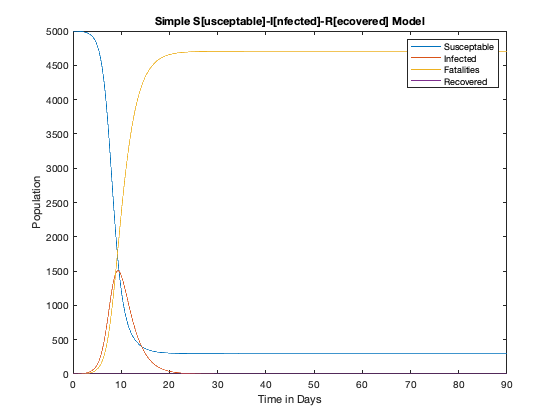


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%
% Plotting it up is another way to do it...

% that first "figure()" command makes the background color white and gives  
%     the graph window a title

figure('Name',  'SIR Model Plot', ...  % that elispis lets you continue
       'Color', 'white')               % a single command on more than one 
                                       % line.  Useful when you want to make
                                       % things look pretty or if you just
                                       % have a lot to do in a single
                                       % line command
                                       
plot(time, S, ...
     time, I, ...
     time, R, ...
     time, F);

xlabel('Time in Days');
ylabel('Population');
title('Simple S[usceptable]-I[nfected]-R[ecovered] Model');
legend('Susceptable','Infected','Fatalities','Recovered');


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%
% End of Program
%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

And that's it!  

A few things to try.

- Simulate a nastier disease (or a more gentle one) and try to combine the terms to have a very high (or low Ro).

- Try to change the number of players to start off with who enter the game ill.

- Change behavior of Sick or Well people when they become ill.  Because being sick cramps your social life.

- Chagne the immunity rate for various levels to demonstrate herd immunity.

Have fun! (and get your flu shot!).